Load and display images

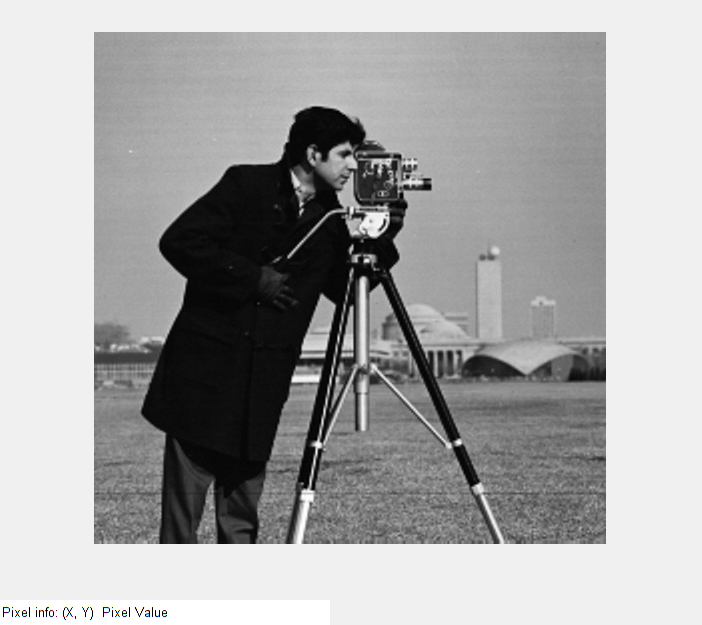

cd 'C:\Users\Roman\Repositories\tutorials\dip-matlab';
[w, wmap] = imread('images/cameraman.png');
figure,imshow(w,wmap),impixelinfo

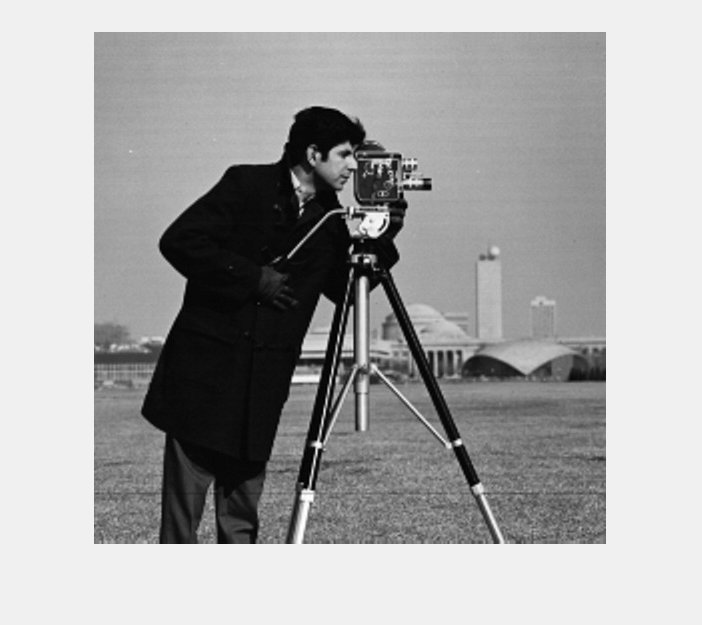

imshow('images/cameraman.png')

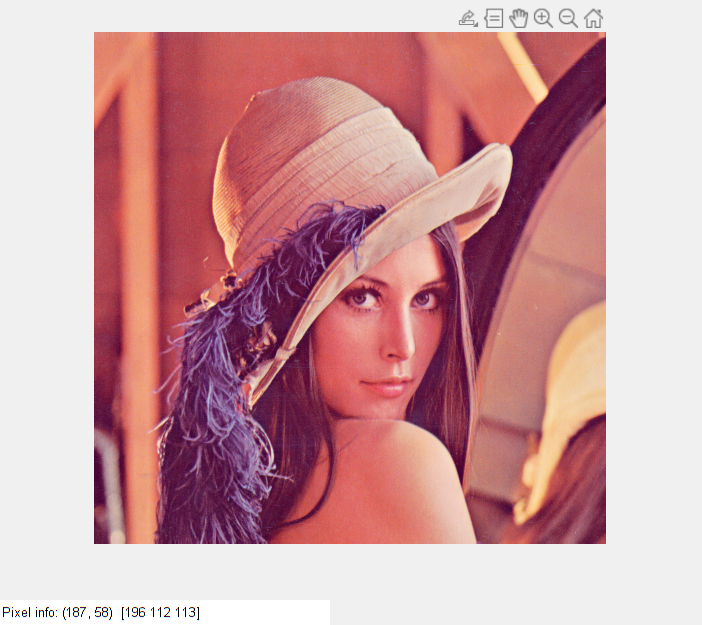

b = imread('images\lena.png');
figure,imshow(b),impixelinfo

Get intensity of pixels

size(b)

ans =    512   512     3


b(100,200,2)

ans = uint8
103

b(100,200,1:3)

ans = 1×1×3 uint8 array
ans(:,:,1) =

   195


ans(:,:,2) =

   103


ans(:,:,3) =

   120


b(100,200,:)

ans = 1×1×3 uint8 array
ans(:,:,1) =

   195


ans(:,:,2) =

   103


ans(:,:,3) =

   120


impixel(b,200,100)

ans =    195   103   120


impixel(w,100,200)

ans =      6     6     6


Indexed image

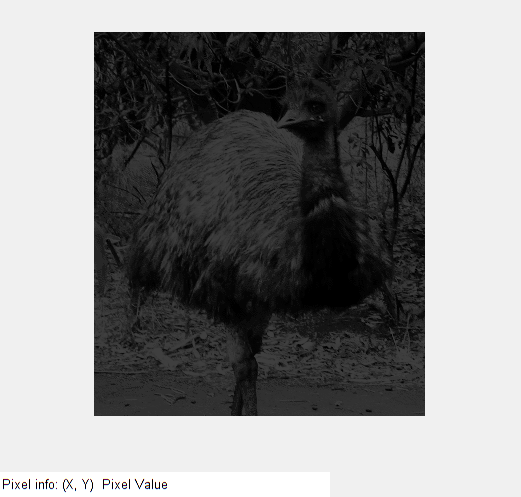

em = imread('images\emu.png');
figure,imshow(em),impixelinfo

Obtain color map of the indexed image

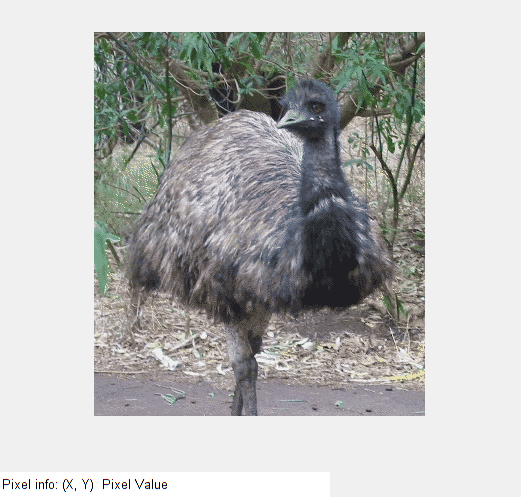

[em,emap] = imread('images\emu.png');
figure,imshow(em,emap),impixelinfo

v = em(109,61)

v = uint8
37

Indexes are encoded as 8-bit numbers, index 37 is obtain by

emap(38,:)

ans =     0.5804    0.5412    0.5098


imfinfo('images/emu.png')

ans = struct with fields:
                  Filename: 'C:\Users\Roman\Repositories\tutorials\dip-matlab\images\emu.png'
               FileModDate: '01-Oct-2021 14:05:25'
                  FileSize: 71714
                    Format: 'png'
             FormatVersion: []
                     Width: 331
                    Height: 384
                  BitDepth: 8
                 ColorType: 'indexed'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: [256×3 double]
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: 2834
               YResolution: 2834
            ResolutionUnit: 'meter'
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              Imag

Numeric types

a = 23;
b = uint8(a);
whos a b

  Name      Size            Bytes  Class     Attributes

  a         1x1                 8  double              
  b         1x1                 1  uint8               



imwrite(w, wmap, 'images\cameraman2.png')

hexdump('images\cameraman.png',10)

Error using idivide>idivide_check (line 87)
At least one argument must belong to an integer class.

Error in idivide (line 42)
idivide_check(a,b);

Error in hexdump (